## AAE 364 HW11

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE364\matlab\matlab_output\hw11';
set(groot, 'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

% Bode plot options
opts_bd = bodeoptions('cstprefs');
opts_bd.Title.Interpreter = "latex";
opts_bd.XLabel.Interpreter = "Latex";
opts_bd.YLabel.Interpreter = "Latex";
opts_bd.Grid = 'on';

% Nyquist plot options
opts_nq = nyquistoptions("cstprefs");
opts_nq.Title.Interpreter = 'latex';
opts_nq.XLabel.Interpreter = "Latex";
opts_nq.YLabel.Interpreter = "Latex";
opts_nq.Grid = 'on';


## B-7-3

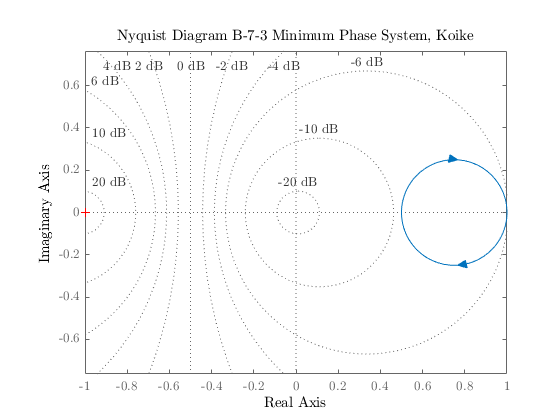

% Minimum Phase System
num = [1 1];
den = [2 1];
G = tf(num,den);
arr_log = [0 -0.15 -2 -4 -5.8];
arr = 10.^(arr_log/20);
% Nyquist Plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram B-7-3 Minimum Phase System, Koike";
    nyquistplot(G,opts_nq);
    axis equal;
saveas(fig,fullfile(fdir,"B-7-3_min_nyquist.png"));

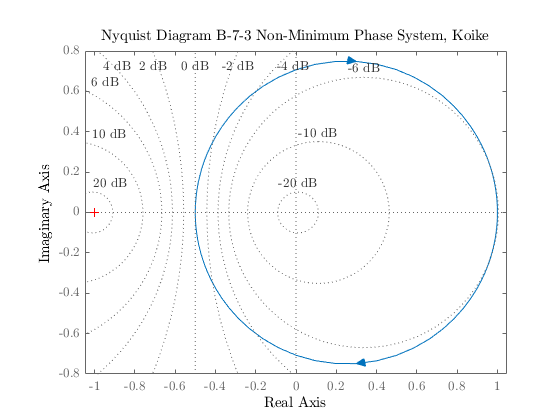


% Non-minimum Phase System
num = [-1 1];
den = [2 1];
G = tf(num,den);
arr_log = [0 -0.01 -2.5 -4 -5.9];
arr = 10.^(arr_log/20);
% Nyquist Plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram B-7-3 Non-Minimum Phase System, Koike";
    nyquistplot(G,opts_nq);
    axis equal;
saveas(fig,fullfile(fdir,"B-7-3_nonmin_nyquist.png"));

## B-7-8

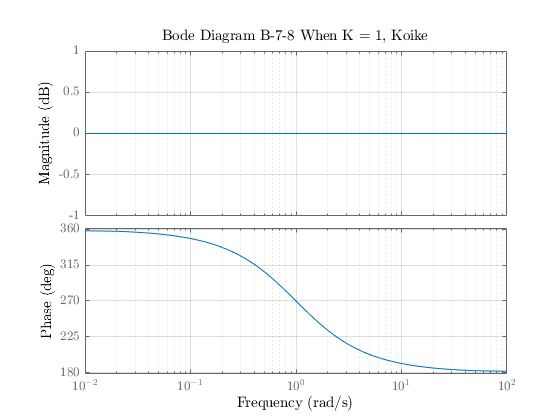

K = 1;
num = K*[-1 1];
den = [1 1];
G = tf(num,den);
% Bode Plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram B-7-8 When K = 1, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"B-7-8_bode_K=1.png"));

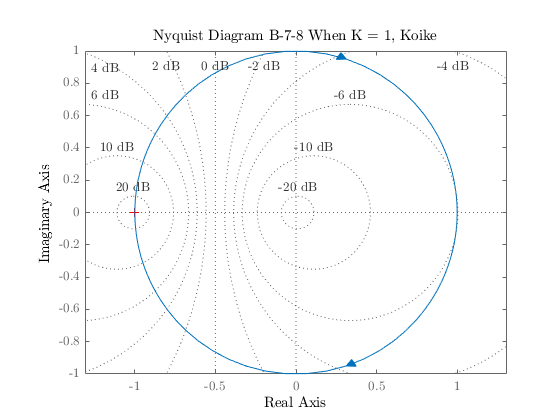

% Nyquist Plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram B-7-8 When K = 1, Koike";
    nyquistplot(G,opts_nq);
    axis equal;
saveas(fig,fullfile(fdir,"B-7-8_nyquist_K=1.png"));

## B-7-10

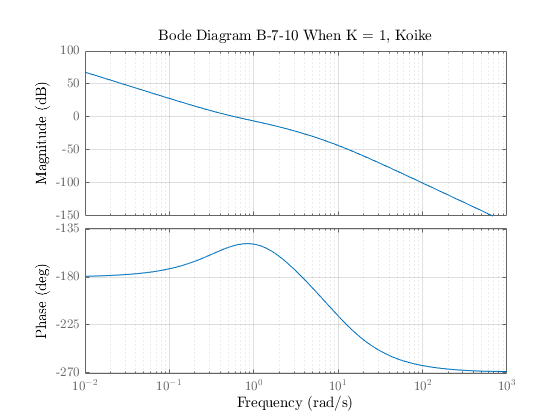

% Define the OL transfer function
num = 5*[2 1];
den = conv(2*[0.5 1 0 0],10*[0.1 1]);
K = 1;
G = tf(K*num,den);
% Bode Plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram B-7-10 When K = 1, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"B-7-10_bode_K=1.png"));

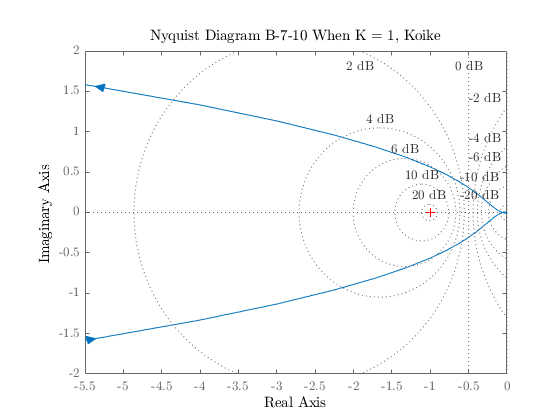

arr_log = [55 28 -7 -48 -100];
arr = 10.^(arr_log/20);
% Nyquist Plot
fig = figure("Renderer","painters");
    title_txt = sprintf("Nyquist Diagram B-7-10 When K = 1, Koike");
    opts_nq.Title.String = title_txt;
    nyquistplot(G,opts_nq);
    xlim([-5.5 0])
    file_txt = sprintf("B-7-10_nyquist_K=1.png");
saveas(fig,fullfile(fdir,file_txt));

## B-7-13

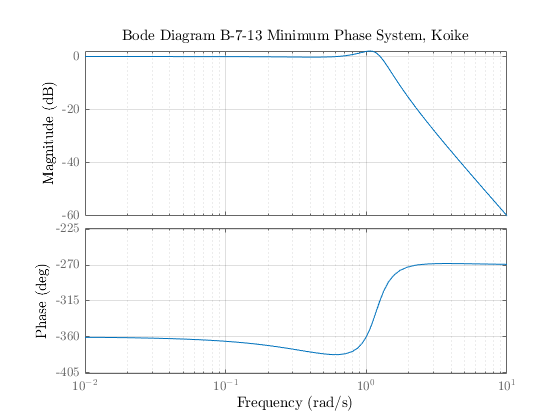

% Define the transfer function 
num = [0 1];
den = [1 0.2 1 1];
G = tf(num,den);
% Bode Plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram B-7-13 Minimum Phase System, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"B-7-13_bode.png"));

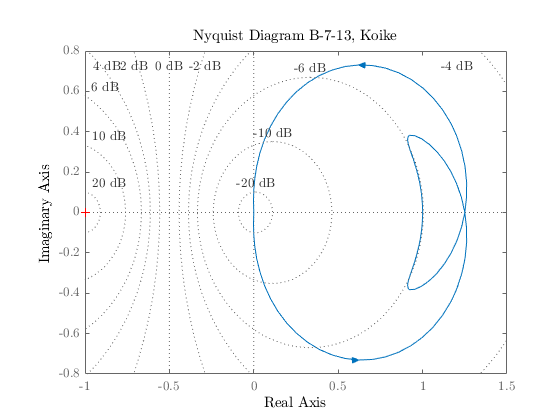

% Nyquist Plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram B-7-13, Koike";
    nyquistplot(G,opts_nq);
saveas(fig,fullfile(fdir,"B-7-13_nyquist.png"));

## P2

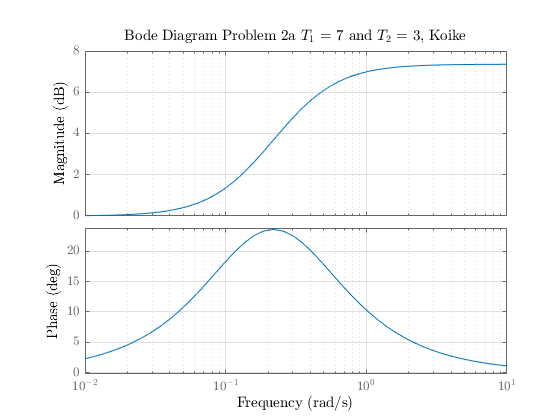

% (a)
num = [7 1];
den = [3 1];
G = tf(num,den);
% Bode Plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram Problem 2a $T_1$ = 7 and $T_2$ = 3, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P2-a_bode.png"));

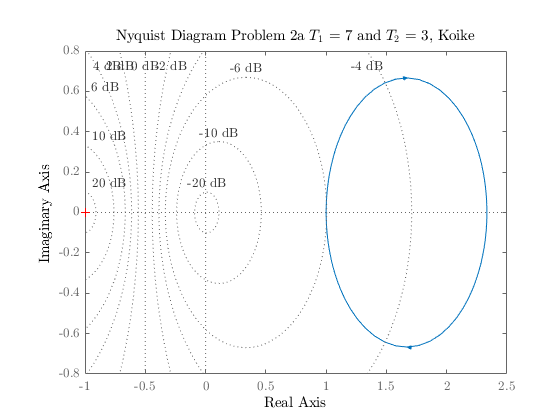

% Nyquist Plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram Problem 2a $T_1$ = 7 and $T_2$ = 3, Koike";
    nyquistplot(G,opts_nq);
saveas(fig,fullfile(fdir,"P2-a_nyquist.png"));

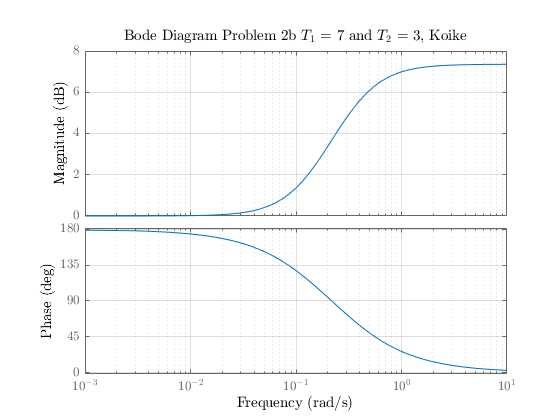


% (b)
num = [7 -1];
den = [3 1];
G = tf(num,den);
% Bode Plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram Problem 2b $T_1$ = 7 and $T_2$ = 3, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P2-b_bode.png"));

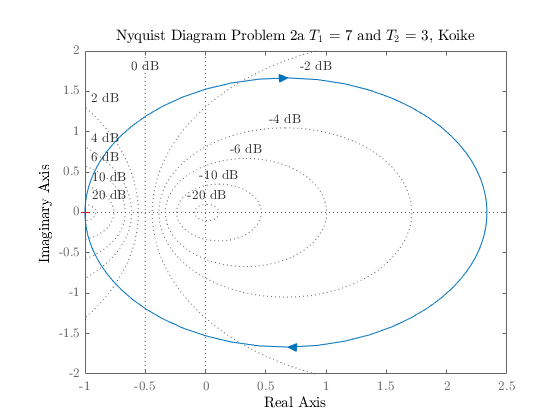

% Nyquist Plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram Problem 2a $T_1$ = 7 and $T_2$ = 3, Koike";
    nyquistplot(G,opts_nq);
saveas(fig,fullfile(fdir,"P2-b_nyquist.png"));

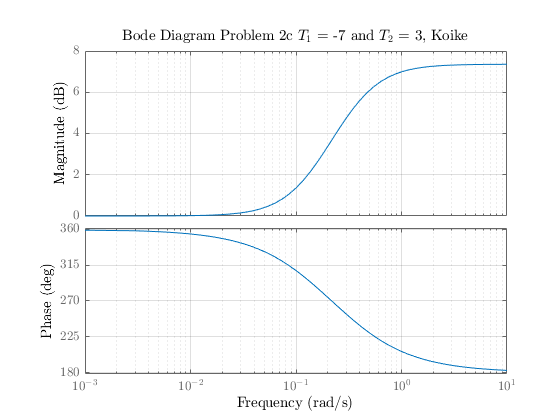


% (c)
num = [-7 1];
den = [3 1];
G = tf(num,den);
% Bode Plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram Problem 2c $T_1$ = -7 and $T_2$ = 3, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P2-c_bode.png"));

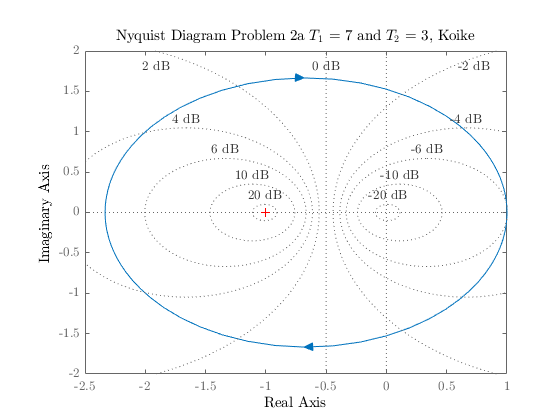

% Nyquist Plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram Problem 2a $T_1$ = 7 and $T_2$ = 3, Koike";
    nyquistplot(G,opts_nq);
saveas(fig,fullfile(fdir,"P2-c_nyquist.png"));

## P3 Aircraft Example

% 1
num = [1.1057 0.19];
den = [1 0.7385 0.8008 0];
G = tf(num,den);

pls = roots(den)

pls =    0.0000 + 0.0000i
  -0.3693 + 0.8151i
  -0.3693 - 0.8151i


zrs = roots(num)

zrs = -0.1718

cornFreq = corner_freq(num,den)

cornFreq = 2×2 table
     Poles      Zeros 
    _______    _______

          0    0.17184
    0.89487        NaN


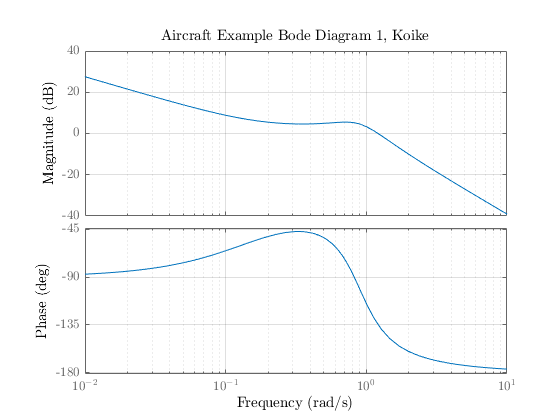


fig = figure("Renderer","painters");
    opts_bd.Title.String = "Aircraft Example Bode Diagram 1, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P3-1_bode.png"));

% 2
num = [1.1057 -0.19];
den = [1 17.95 123.3 366.3 112.2 0];

pls = roots(den)

pls =    0.0000 + 0.0000i
  -8.0992 + 0.0000i
  -4.7533 + 4.2012i
  -4.7533 - 4.2012i
  -0.3442 + 0.0000i


zrs = roots(num)

zrs = 0.1718

cornFreq = corner_freq(num,den)

cornFreq = 4×2 table
     Poles      Zeros 
    _______    _______

          0    0.17184
    0.34423        NaN
     6.3438        NaN
     8.0992        NaN


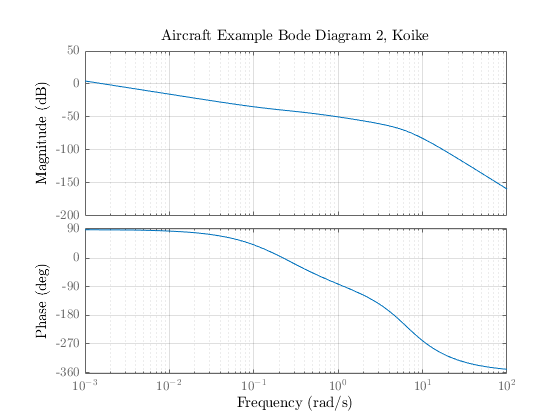


G = tf(num,den);
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Aircraft Example Bode Diagram 2, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P3-2_bode.png"));

## P4 Spacecraft Example

num = 0.036*[1 25];
den = [1 0.04 1 0 0];

pls = roots(den)

pls =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0200 + 0.9998i
  -0.0200 - 0.9998i


zrs = roots(num)

zrs = -25

cornFreq = corner_freq(num,den)

cornFreq = 2×2 table
    Poles    Zeros
    _____    _____

      0        25 
      1       NaN 


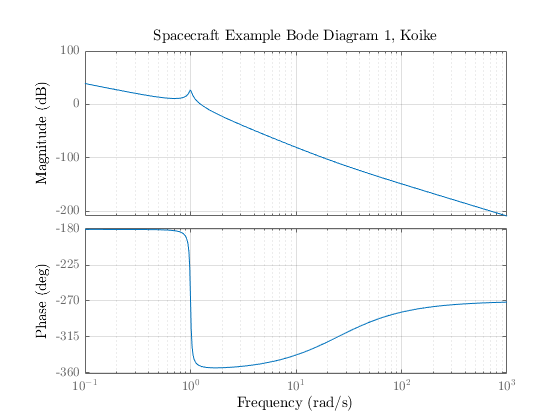


G = tf(num,den);
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Spacecraft Example Bode Diagram 1, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P4_bode.png"));